# Load data

clear all; close all;
addpath('./MatlabFuncs/')

load('Data/Param_Fit2.mat', 'x_both'); %%mac syntax
% load('Data\Param_Fit2.mat', 'x_both');
load('Data/Param_Fit3.mat', 'x_all'); %%mac syntax
% load('Param_Fit3.mat', 'x_all');

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

run('./MatlabFuncs/FuncGenerator.m');

auxins = logspace(-2,2,100);

# Time Trajectories 

## *Varied initial Conditions*

param = x_all %x_both; 

param =     0.0416    0.0590    0.1663    0.0260   16.2997    7.7079    1.5070    0.7421


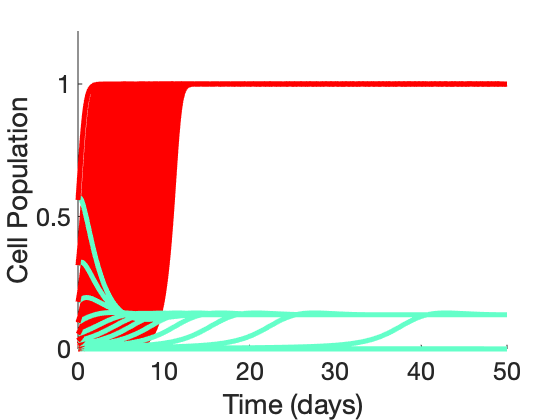


tspan = linspace(0, 50 * 24, 1000);

%Set known values
B_ext = 50; %ug
AP = 20; %uM

c0 = logspace(-5, -0.25, 20);
a0 = 10; %linspace(5,20,5);
[A1, N1] = meshgrid(a0,c0);

figure(1);

cir_on = [];
cir_off = [];

for i = 1 : numel(A1)
    y0 = [A1(i), N1(i)];
    [t,f] = ode45(@(t,y) DynSys(t,y,param,B_ext,AP),tspan,y0');
    [tc,fc] = ode45(@(t,y) DynSys(t,y,param,0,0),tspan,y0');
    
    cir_on = [cir_on, f(:,2)];
    cir_off = [cir_off, fc(:,2)];
    
    hold on;
    plot(tspan./24,f(:,2),'k','Linewidth',5,'Color',[100,255,201]./255)
    plot(tspan./24,fc(:,2),'k','Linewidth',5,'Color',[1,0,0])
end

save("Data\Dynamcs.mat", "cir_on", "cir_off", "tspan");

xlabel('Time (days)')
ylabel('Cell Population')

ax1 = gca;
ax1.FontSize = 25;

## *Paradoxical Feedback Response to Mutation*

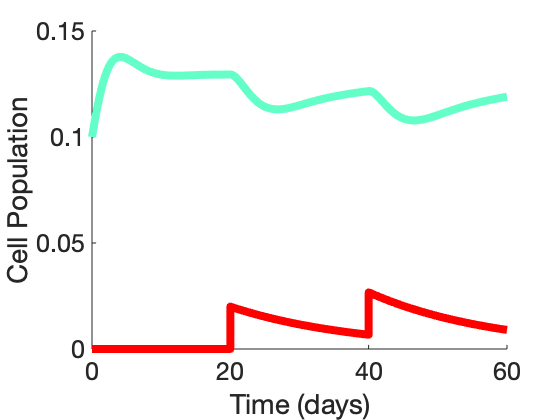

T1 = 20;
tspan1 = linspace(0,T1*24,1000);
y01 = [10, 0.1, 0];

[t1,f1] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan1,y01');

%1st mutation
T2 = 40;
tspan2 = linspace(T1*24,T2*24,1000);
y02 = f1(end,:) + [0, 0, 0.02];

[t2,f2] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan2,y02');

%2nd mutation
T3 = 60;
tspan3 = linspace(T2*24,T3*24,1000);
y03 = f2(end,:) + [0, 0, 0.02];

[t3,f3] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan3,y03');

t_all = [t1; t2; t3];
f_all = [f1; f2; f3];

save("Data\Dynamcs_mut1.mat", 't_all', 'f_all')

figure(2)
clf; hold on;

plot(t_all./24, f_all(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all./24, f_all(:,3), 'LineWidth', 8, 'Color', [1,0,0]);

xlabel('Time (days)')
ylabel('Cell Population')
xlim([0, 60])
ax2 = gca;
ax2.FontSize = 25;
box off;

## *Simple Feedback Response to Mutation*

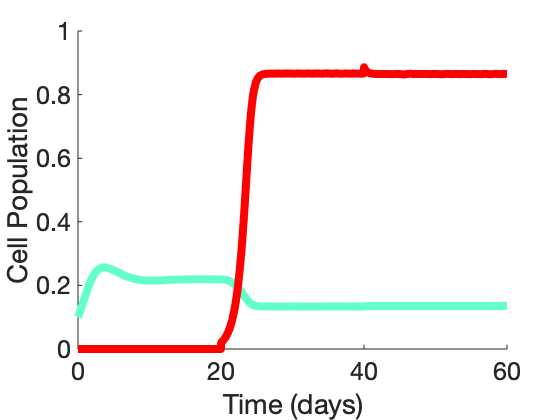

x_both_sf = param;
x_both_sf(2) = 0;

tspan1 = linspace(0,T1*24,1000);
y01 = [10, 0.1, 0];

[t1,f1] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,AP),tspan1,y01');

%1st mutation
tspan2 = linspace(T1*24,T2*24,1000);
y02 = f1(end,:) + [0, 0, 0.02];

[t2,f2] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,AP),tspan2,y02');

%2nd mutation
tspan3 = linspace(T2*24,T3*24,1000);
y03 = f2(end,:) + [0, 0, 0.02];

[t3,f3] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,AP),tspan3,y03');

t_all = [t1; t2; t3];
f_all = [f1; f2; f3];

save("Data\Dynamcs_mut2.mat", 't_all', 'f_all')

figure(3)
clf; hold on;

plot(t_all./24, f_all(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all./24, f_all(:,3), 'LineWidth', 8, 'Color', [1,0,0]);

xlabel('Time (days)')
ylabel('Cell Population')
xlim([0, 60])
ax3 = gca;
ax3.FontSize = 25;
box off;